# Setup

## Set Parameters for Chronux 

% Setting parameters
params.Fs = 1000; %Sampling frequency of input data (1000 = 1000 hz = 1 sample per millisecond)
params.fpass = [0 100]; % Which frequencies to look at [lowest_wanted highest_wanted]
params.pad = 0; % will add 0's to fit into a power of 2 for better calculation (0 is default and adds 0's to the next power of 2)
TW = 5; % the time-bandwidth product 
K = 9; % the number of tapers, K = 2*TW - 1 
params.tapers = [TW K]; 
params.err = [2 0.05]

params = struct with fields:
        Fs: 1000
     fpass: [0 100]
       pad: 0
    tapers: [5 9]
       err: [2 0.0500]


## Set General Parameters


Gparams.window = 20

Gparams = struct with fields:
                   window: 20
                movingwin: [20 1]
                    alpha: 0.9965
         standardized_len: 0
    artifact_filter_limit: 0.5000


Gparams.movingwin = [20 1]

Gparams = struct with fields:
                   window: 20
                movingwin: [20 1]
                    alpha: 0.9965
         standardized_len: 0
    artifact_filter_limit: 0.5000


Gparams.alpha = 0.9965

Gparams = struct with fields:
                   window: 20
                movingwin: [20 1]
                    alpha: 0.9965
         standardized_len: 0
    artifact_filter_limit: 0.5000


Gparams.standardized_len= 0

Gparams = struct with fields:
                   window: 20
                movingwin: [20 1]
                    alpha: 0.9965
         standardized_len: 0
    artifact_filter_limit: 0.5000


Gparams.artifact_filter_limit = 0.5

Gparams = struct with fields:
                   window: 20
                movingwin: [20 1]
                    alpha: 0.9965
         standardized_len: 0
    artifact_filter_limit: 0.5000


##  Load Each Dataset

I have removed CT7 and KO7 here as the trials were noisy

**** Take out Trial #4 as well - this one has large 52 hz noise

% Load each unhabituated trial for each
controls = {CT1, CT2, CT3, CT5, CT6, CT8}

controls = 1×7 cell array
    {1893260×2 single}    {3726858×2 single}    {3716176×2 single}    {3675772×2 single}    {3640352×2 single}    {3615364×2 single}    {3653016×2 single}


knockouts = {KO1, KO2, KO3, KO5, KO6, KO8}

knockouts = 1×7 cell array
    {1890190×2 single}    {3689071×2 single}    {3517539×2 single}    {3770358×2 single}    {3691845×2 single}    {3938323×2 single}    {3861380×2 single}


## Vertically Concatenate Datasets

CT_cat = vertcat_cell_array(controls);
KO_cat = vertcat_cell_array(knockouts);

ans = 'Processing Control 1.000000'


ans =

  1×0 empty char array



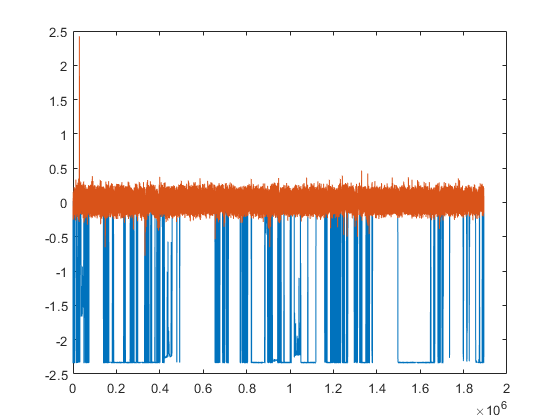

result = 1892886×2 single matrix
    0.0123   -0.0489
    0.0136   -0.0591
    0.0165   -0.0742
    0.0149   -0.0644
    0.0156   -0.0772
    0.0123    0.0008
    0.0146   -0.0048
    0.0152   -0.0098
    0.0136   -0.0223
    0.0156   -0.0390


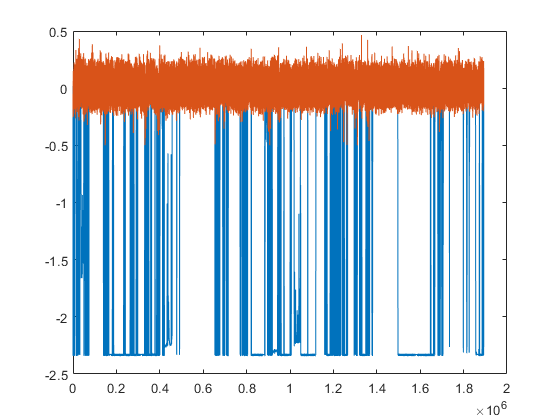

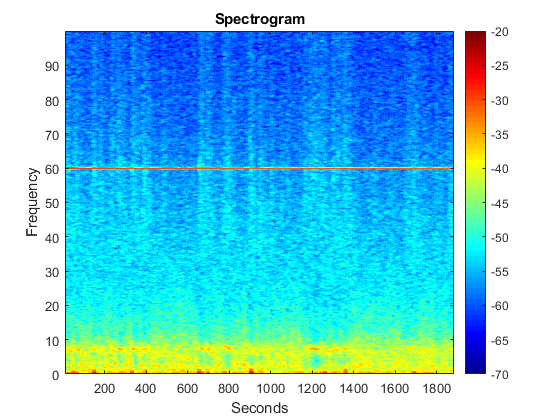

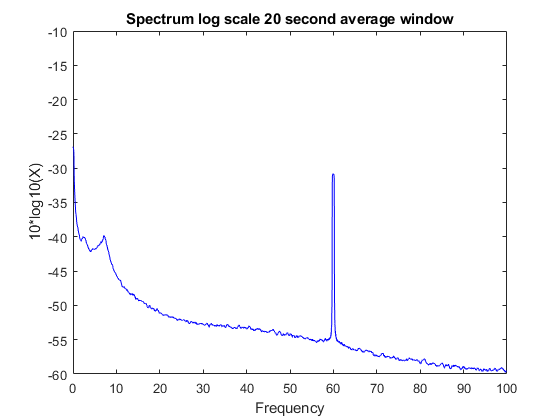

result = 1×3 cell array
    {3277×1 single}    {1×3277 double}    {3277×1 single}


ans = 'Processing Control 2.000000'


ans =

  1×0 empty char array



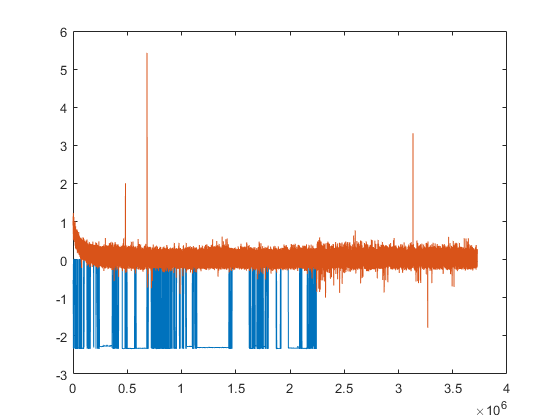

result = 3688469×2 single matrix
    0.0073    0.4879
    0.0073    0.4951
    0.0063    0.4685
    0.0067    0.4922
    0.0054    0.4905
    0.0067    0.4826
    0.0077    0.4784
    0.0070    0.4863
    0.0063    0.4928
    0.0054    0.4991


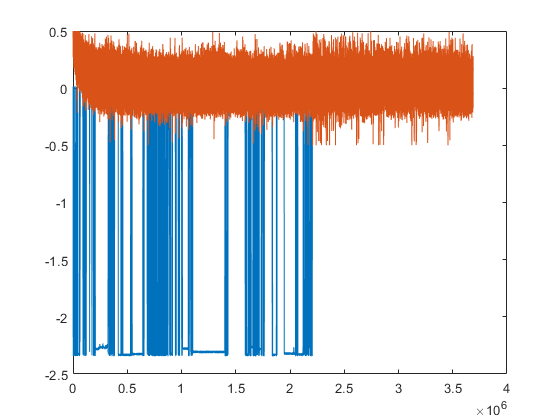

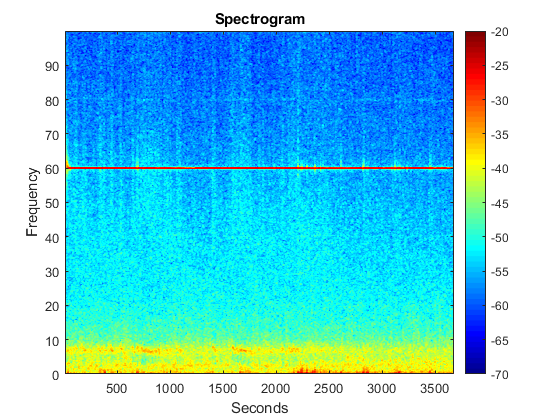

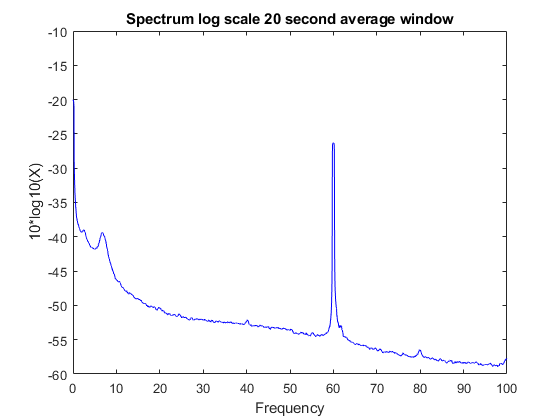

result = 1×3 cell array
    {3277×1 single}    {1×3277 double}    {3277×1 single}


ans = 'Processing Control 3.000000'


ans =

  1×0 empty char array



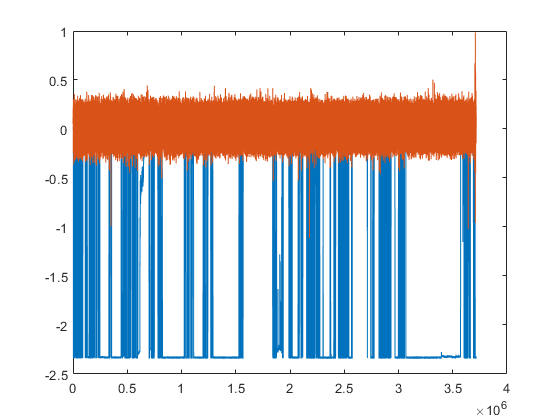

result = 3715351×2 single matrix
    0.0129    0.0524
    0.0103    0.1034
    0.0129    0.1139
    0.0123    0.0554
    0.0113   -0.0117
    0.0139   -0.0473
    0.0133   -0.0506
    0.0133   -0.0581
    0.0139   -0.0137
    0.0100    0.0323


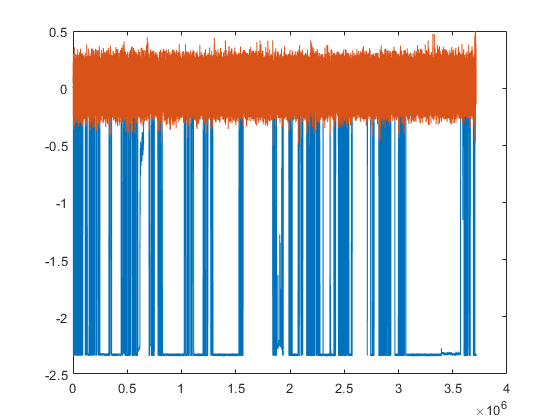

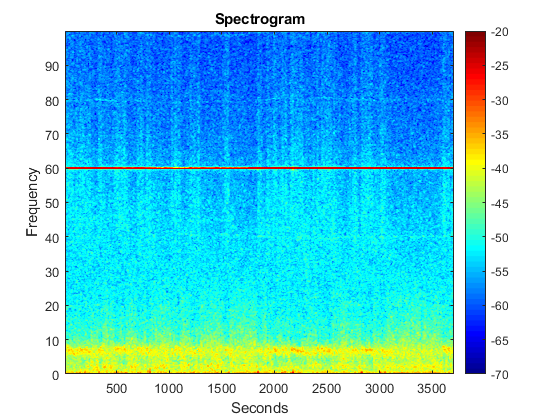

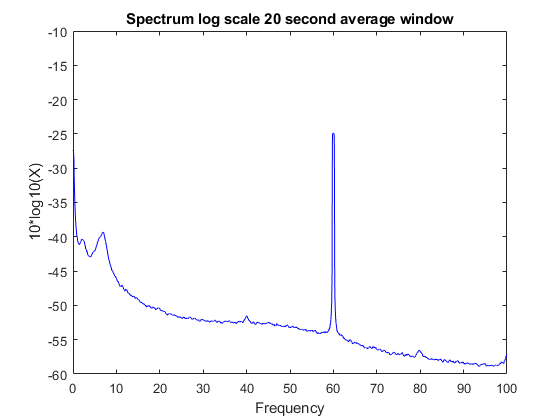

result = 1×3 cell array
    {3277×1 single}    {1×3277 double}    {3277×1 single}


ans = 'Processing Control 4.000000'


ans =

  1×0 empty char array



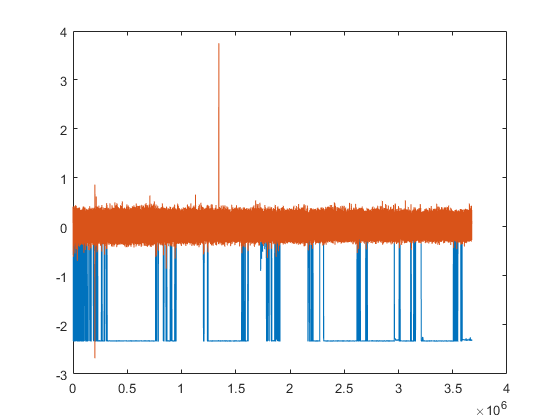

result = 3675532×2 single matrix
    0.0093    0.0728
    0.0119    0.2465
    0.0080    0.1442
    0.0103    0.1261
    0.0106    0.1554
    0.0119   -0.0522
    0.0073   -0.0647
    0.0047   -0.1216
   -0.0065   -0.2802
   -2.2557   -0.2058


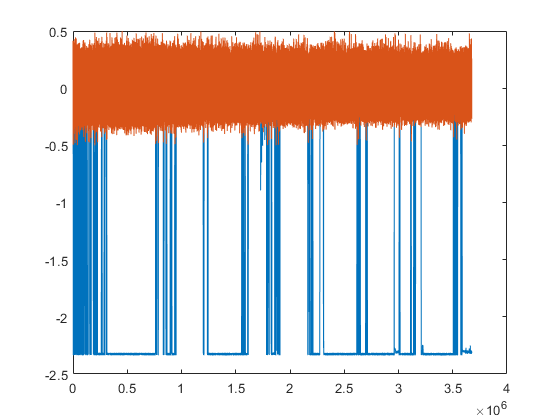

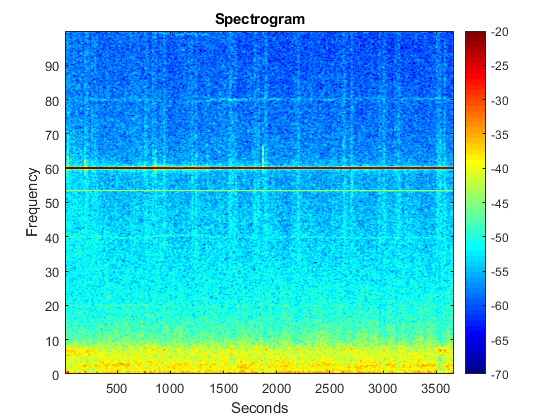

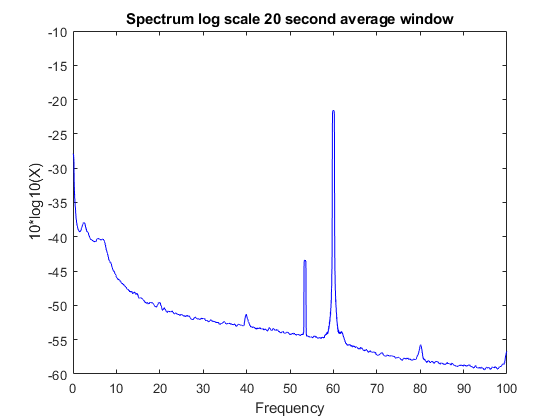

result = 1×3 cell array
    {3277×1 single}    {1×3277 double}    {3277×1 single}


ans = 'Processing Control 5.000000'


ans =

  1×0 empty char array



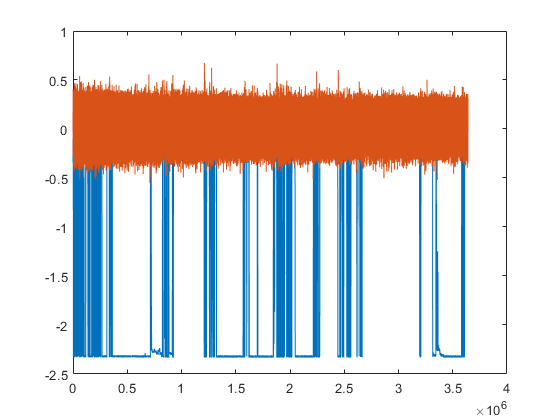

result = 3640060×2 single matrix
   -0.1068   -0.0292
   -0.1163   -0.0654
   -0.1219   -0.0479
   -0.1298    0.0087
   -0.1407    0.0248
   -0.1492    0.0172
   -0.1608    0.0475
   -0.1719    0.0965
   -0.1851    0.2511
   -0.1966    0.2080


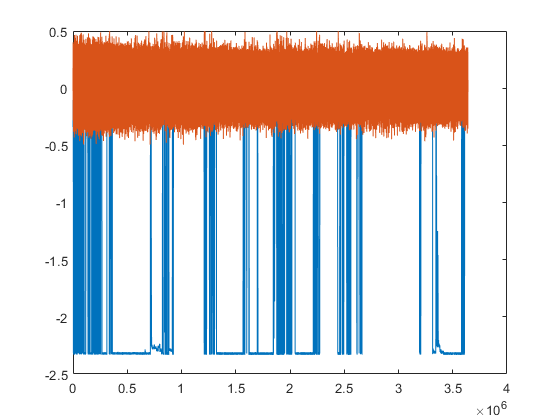

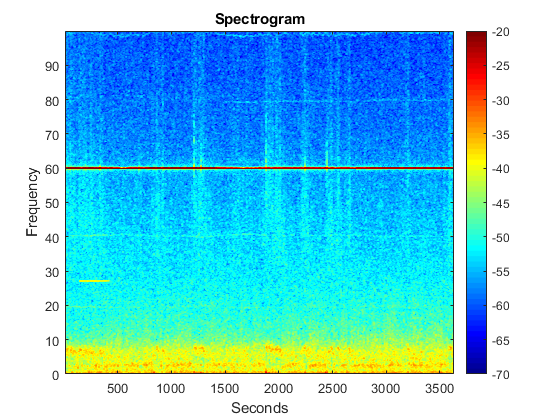

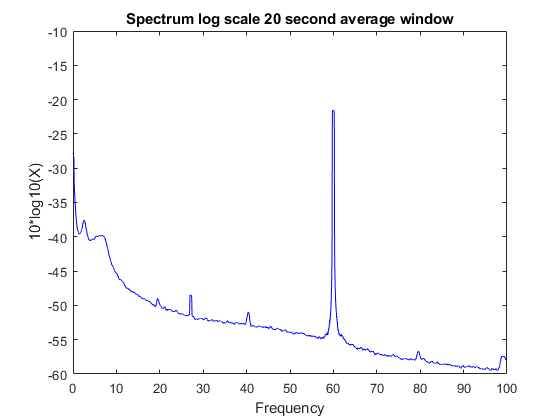

result = 1×3 cell array
    {3277×1 single}    {1×3277 double}    {3277×1 single}


ans = 'Processing Control 6.000000'


ans =

  1×0 empty char array



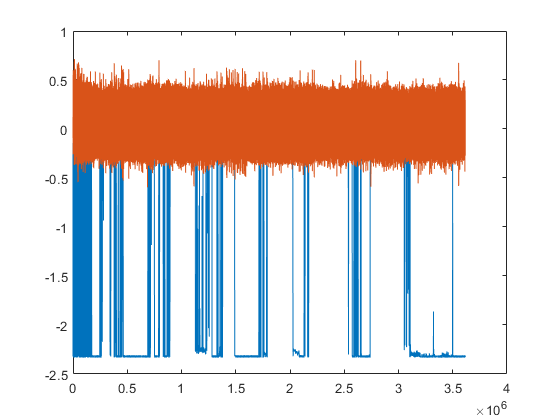

result = 3614066×2 single matrix
   -0.1473    0.1225
    0.0017    0.0649
    0.0037   -0.0499
    0.0067   -0.0476
    0.0047    0.0336
    0.0073    0.0754
    0.0073    0.1215
    0.0070    0.1218
    0.0080    0.2544
    0.0070    0.2231


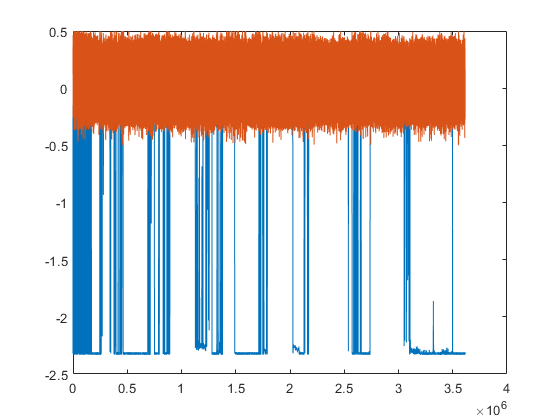

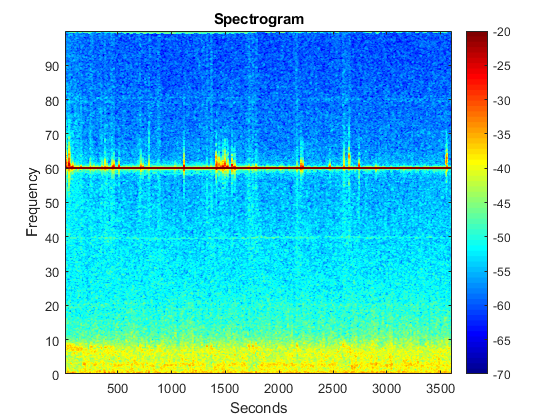

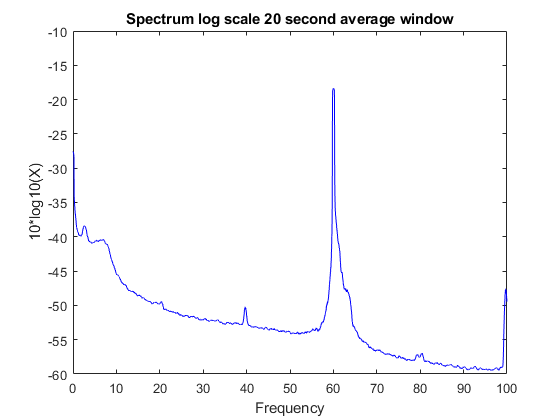

result = 1×3 cell array
    {3277×1 single}    {1×3277 double}    {3277×1 single}


ans = 'Processing Control 7.000000'


ans =

  1×0 empty char array



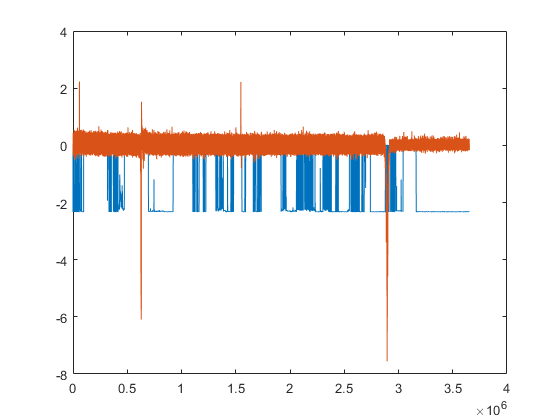

result = 3613944×2 single matrix
    0.0070    0.0498
    0.0133    0.0379
    0.0116    0.1083
    0.0116    0.1336
    0.0103    0.1244
    0.0100    0.2455
   -1.6061    0.0863
   -2.2689    0.2448
   -2.2962    0.2346
   -2.3090    0.1912


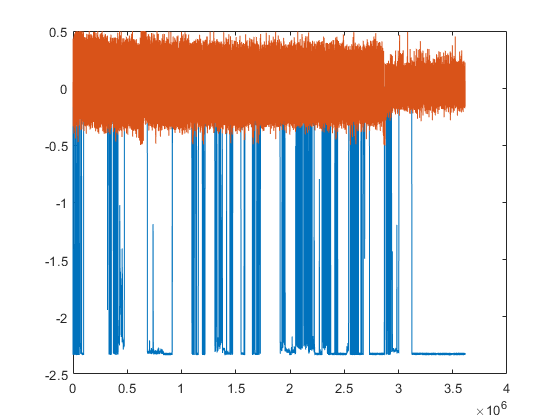

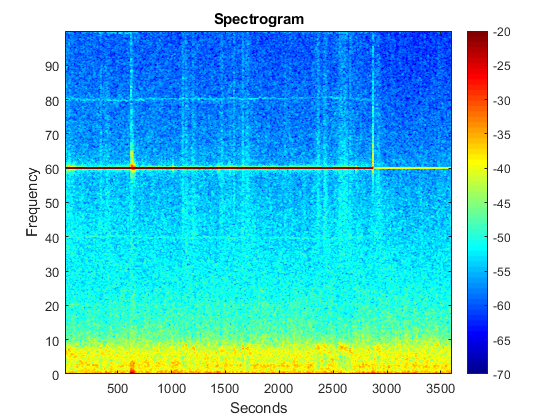

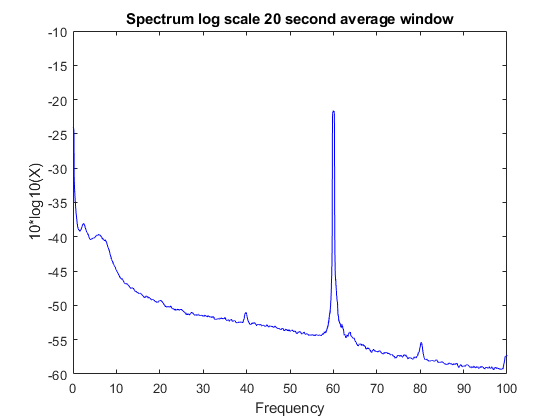

result = 1×3 cell array
    {3277×1 single}    {1×3277 double}    {3277×1 single}


x = 1892886×2 single matrix
    0.0123   -0.0489
    0.0136   -0.0591
    0.0165   -0.0742
    0.0149   -0.0644
    0.0156   -0.0772
    0.0123    0.0008
    0.0146   -0.0048
    0.0152   -0.0098
    0.0136   -0.0223
    0.0156   -0.0390


x = 5581355×2 single matrix
    0.0123   -0.0489
    0.0136   -0.0591
    0.0165   -0.0742
    0.0149   -0.0644
    0.0156   -0.0772
    0.0123    0.0008
    0.0146   -0.0048
    0.0152   -0.0098
    0.0136   -0.0223
    0.0156   -0.0390


x = 9296706×2 single matrix
    0.0123   -0.0489
    0.0136   -0.0591
    0.0165   -0.0742
    0.0149   -0.0644
    0.0156   -0.0772
    0.0123    0.0008
    0.0146   -0.0048
    0.0152   -0.0098
    0.0136   -0.0223
    0.0156   -0.0390


x = 12972238×2 single matrix
    0.0123   -0.0489
    0.0136   -0.0591
    0.0165   -0.0742
    0.0149   -0.0644
    0.0156   -0.0772
    0.0123    0.0008
    0.0146   -0.0048
    0.0152   -0.0098
    0.0136   -0.0223
    0.0156   -0.0390


x = 16612298×2 single matrix
    0.0123   -0.0489
    0.0136   -0.0591
    0.0165   -0.0742
    0.0149   -0.0644
    0.0156   -0.0772
    0.0123    0.0008
    0.0146   -0.0048
    0.0152   -0.0098
    0.0136   -0.0223
    0.0156   -0.0390


x = 20226364×2 single matrix
    0.0123   -0.0489
    0.0136   -0.0591
    0.0165   -0.0742
    0.0149   -0.0644
    0.0156   -0.0772
    0.0123    0.0008
    0.0146   -0.0048
    0.0152   -0.0098
    0.0136   -0.0223
    0.0156   -0.0390


x = 23840308×2 single matrix
    0.0123   -0.0489
    0.0136   -0.0591
    0.0165   -0.0742
    0.0149   -0.0644
    0.0156   -0.0772
    0.0123    0.0008
    0.0146   -0.0048
    0.0152   -0.0098
    0.0136   -0.0223
    0.0156   -0.0390


result = 23840308×2 single matrix
    0.0123   -0.0489
    0.0136   -0.0591
    0.0165   -0.0742
    0.0149   -0.0644
    0.0156   -0.0772
    0.0123    0.0008
    0.0146   -0.0048
    0.0152   -0.0098
    0.0136   -0.0223
    0.0156   -0.0390


Plotting All Together


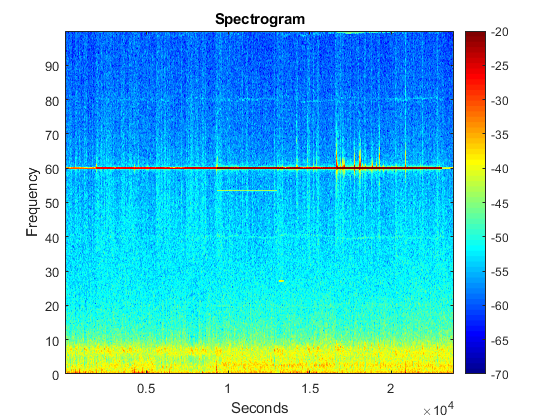

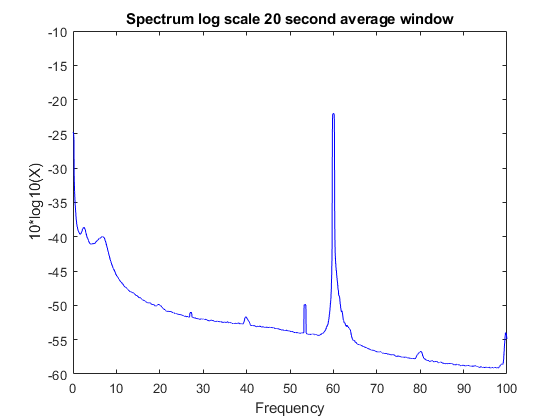

result = 1×3 cell array
    {3277×1 single}    {1×3277 double}    {3277×1 single}


x = 1×1 cell array
    {1×3 cell}


x = 1×2 cell array
    {1×3 cell}    {1×3 cell}


x = 1×3 cell array
    {1×3 cell}    {1×3 cell}    {1×3 cell}


x = 1×4 cell array
    {1×3 cell}    {1×3 cell}    {1×3 cell}    {1×3 cell}


x = 1×5 cell array
    {1×3 cell}    {1×3 cell}    {1×3 cell}    {1×3 cell}    {1×3 cell}


x = 1×6 cell array
    {1×3 cell}    {1×3 cell}    {1×3 cell}    {1×3 cell}    {1×3 cell}    {1×3 cell}


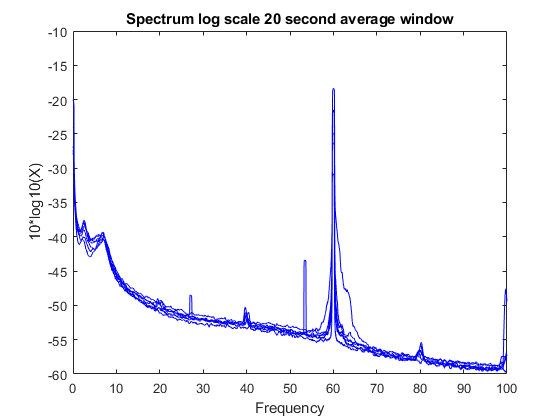

x = 1×7 cell array
    {1×3 cell}    {1×3 cell}    {1×3 cell}    {1×3 cell}    {1×3 cell}    {1×3 cell}    {1×3 cell}


result = 1×7 cell array
    {1×3 cell}    {1×3 cell}    {1×3 cell}    {1×3 cell}    {1×3 cell}    {1×3 cell}    {1×3 cell}



LFP_analysis_i(controls ,params, Gparams, 'Control') 

ans = 'Processing Knockout 1.000000'


ans =

  1×0 empty char array



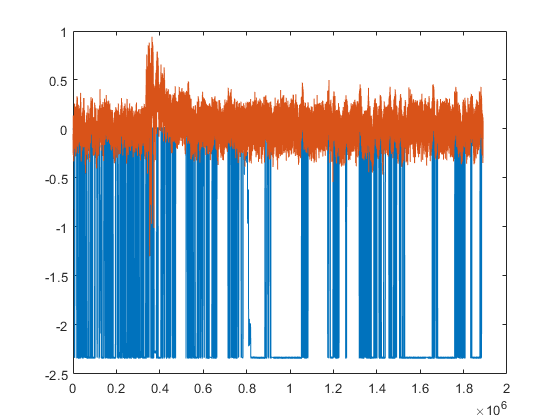

result = 1872965×2 single matrix
    0.0040   -0.0496
    0.0034   -0.0759
    0.0024   -0.0456
    0.0054   -0.0561
    0.0034   -0.0413
    0.0037    0.0103
    0.0044   -0.0802
    0.0050   -0.0506
    0.0031   -0.0677
    0.0027   -0.0693


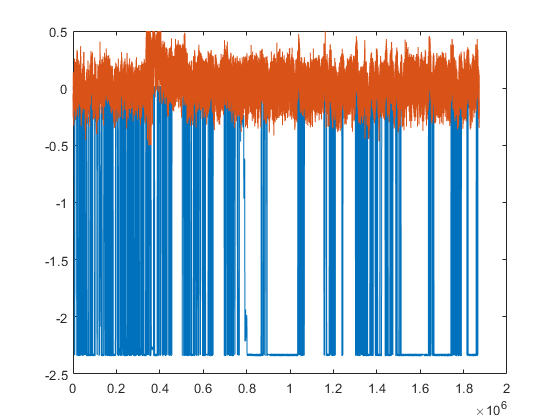

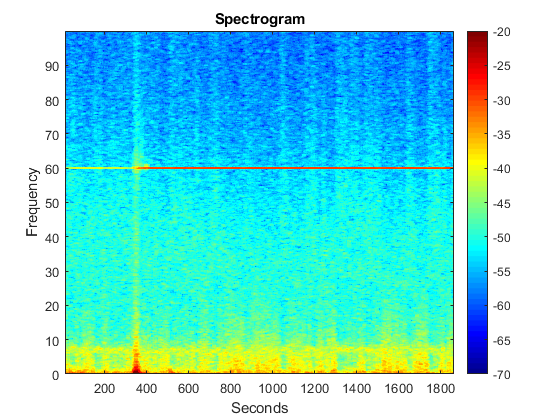

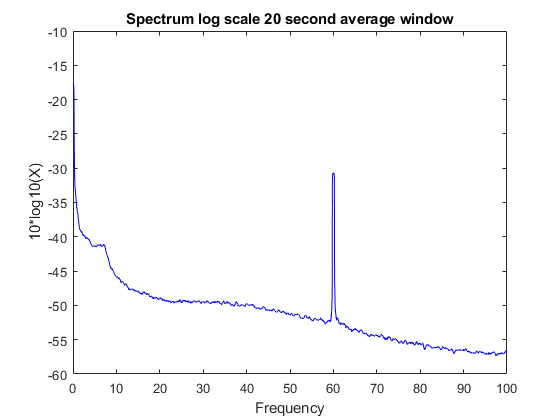

result = 1×3 cell array
    {3277×1 single}    {1×3277 double}    {3277×1 single}


ans = 'Processing Knockout 2.000000'


ans =

  1×0 empty char array



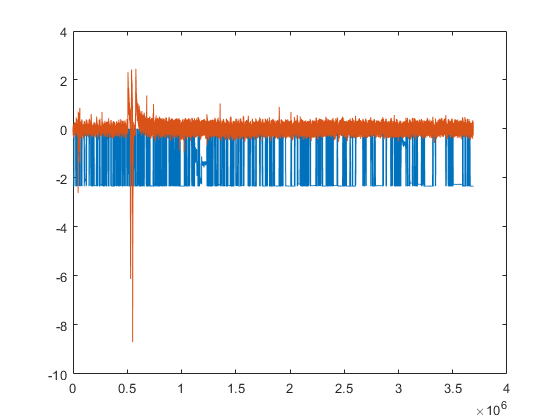

result = 3610252×2 single matrix
   -2.3264    0.0218
   -2.3278    0.0116
   -2.3255    0.0313
   -2.3261    0.0379
   -2.3281    0.0366
   -2.3278    0.0221
   -2.3264   -0.0193
   -2.3281   -0.0298
   -2.3268   -0.0614
   -2.3274   -0.0601


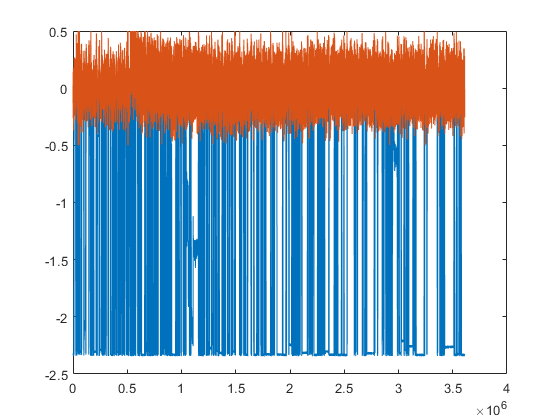

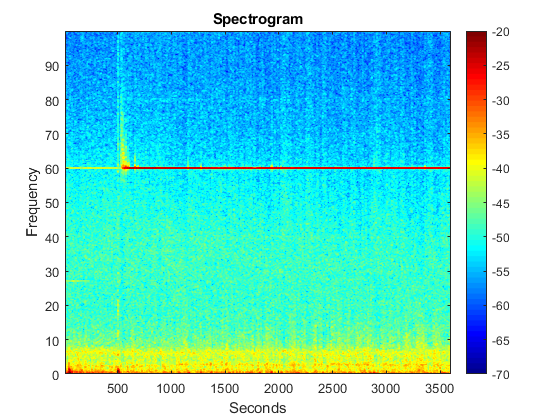

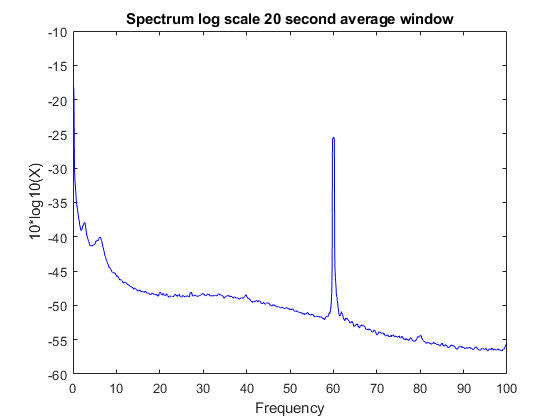

result = 1×3 cell array
    {3277×1 single}    {1×3277 double}    {3277×1 single}


ans = 'Processing Knockout 3.000000'


ans =

  1×0 empty char array



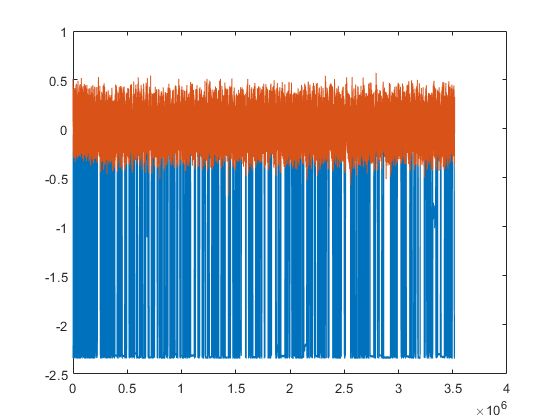

result = 3517509×2 single matrix
   -2.3264    0.0705
   -2.3287    0.0909
   -2.3284    0.0866
   -2.3281    0.1356
   -2.3284    0.1498
   -2.3287    0.1343
   -2.3284    0.1823
   -2.3297    0.1254
   -2.3284    0.0685
   -2.3294    0.0850


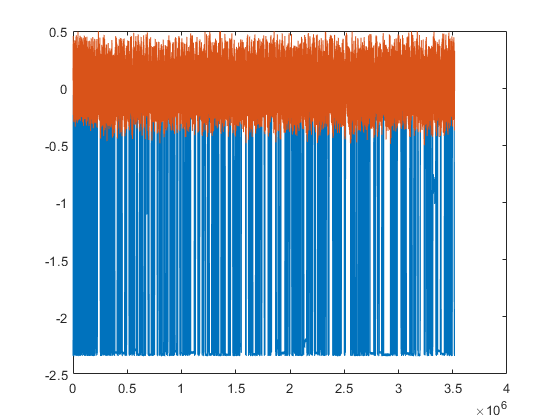

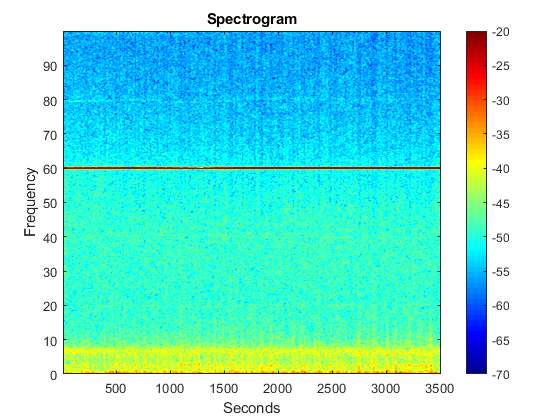

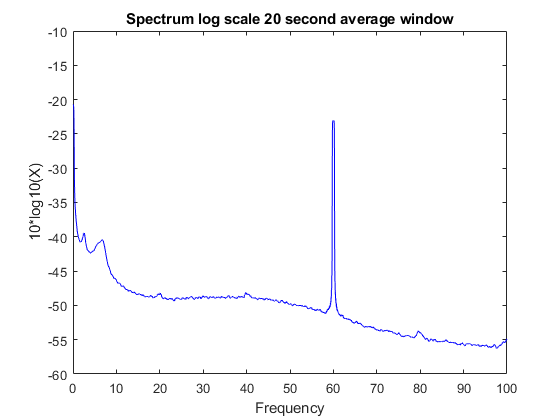

result = 1×3 cell array
    {3277×1 single}    {1×3277 double}    {3277×1 single}


ans = 'Processing Knockout 4.000000'


ans =

  1×0 empty char array



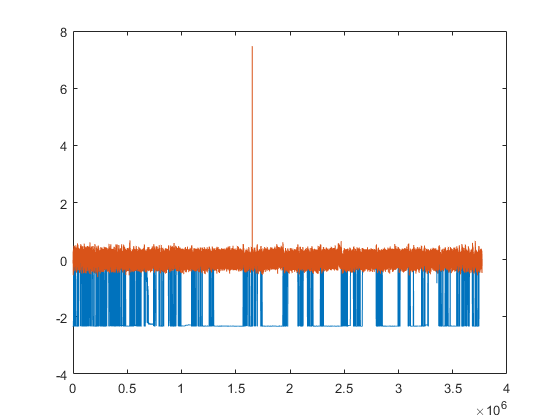

result = 3769937×2 single matrix
   -2.3205   -0.1390
   -2.3228   -0.1091
   -2.3235   -0.0134
   -2.3215    0.0267
   -2.3199    0.1402
   -2.3215    0.0771
   -2.3205    0.0254
   -2.3195   -0.0183
   -2.3228   -0.1348
   -2.3225   -0.1904


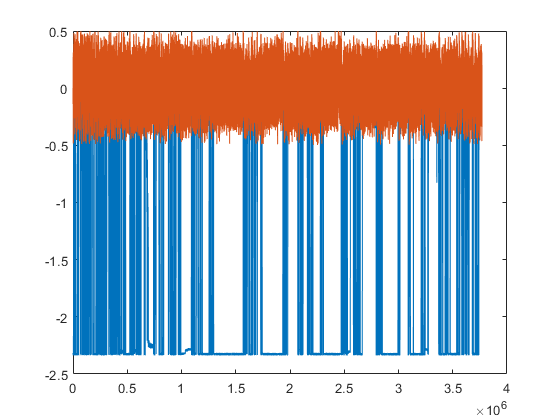

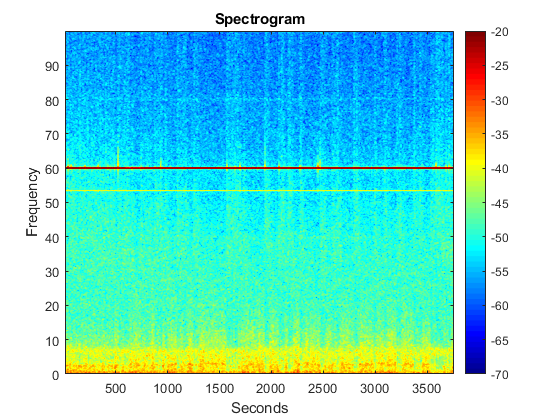

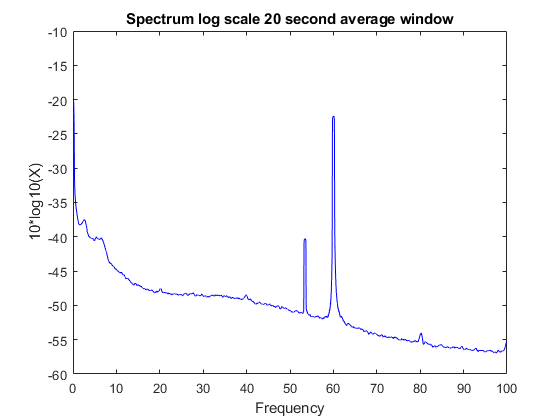

result = 1×3 cell array
    {3277×1 single}    {1×3277 double}    {3277×1 single}


ans = 'Processing Knockout 5.000000'


ans =

  1×0 empty char array



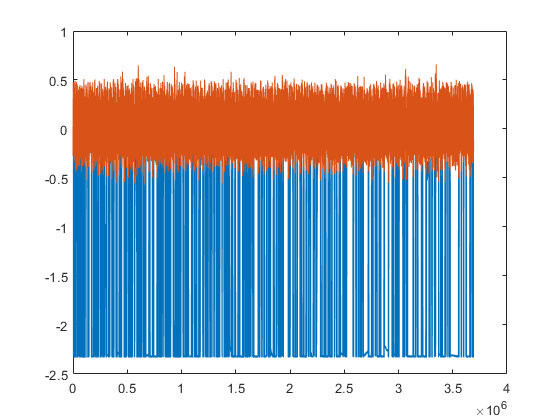

result = 3691467×2 single matrix
    0.0100    0.0175
    0.0077    0.0570
    0.0100    0.0300
    0.0106    0.0419
    0.0087    0.0481
    0.0080    0.1297
    0.0093    0.1304
    0.0083    0.0853
    0.0106    0.1484
    0.0096    0.2330


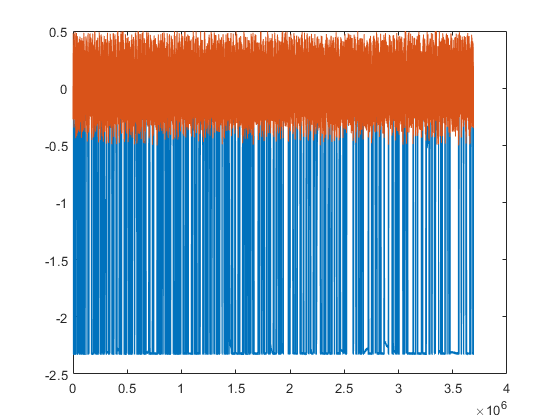

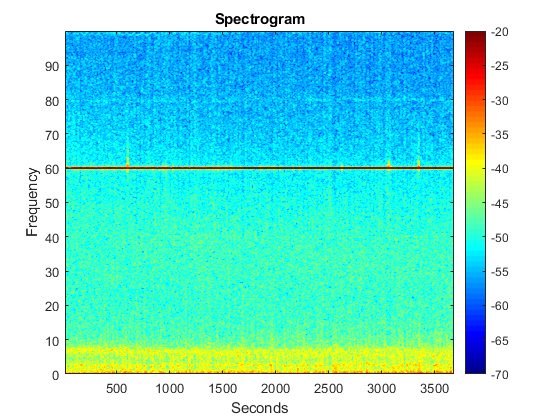

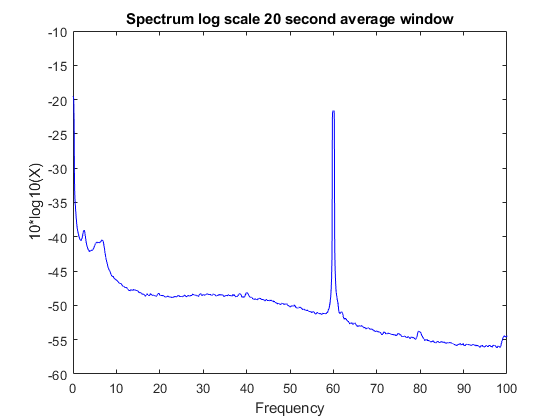

result = 1×3 cell array
    {3277×1 single}    {1×3277 double}    {3277×1 single}


ans = 'Processing Knockout 6.000000'


ans =

  1×0 empty char array



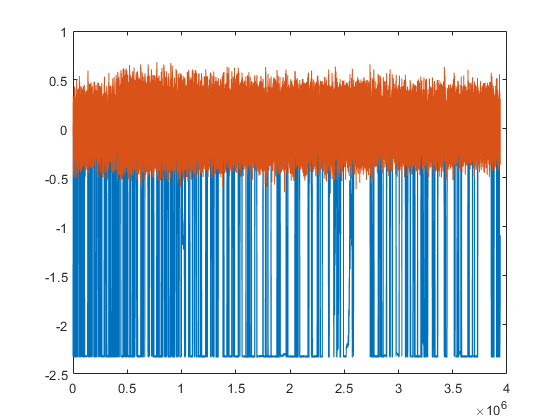

result = 3935536×2 single matrix
   -2.3156   -0.0703
   -2.3149   -0.0614
   -2.3149    0.0142
   -2.3139    0.1715
   -2.3143    0.1879
   -2.3149    0.0376
   -2.3126    0.0297
   -2.3136   -0.0581
   -2.3126   -0.0506
   -2.3143   -0.2190


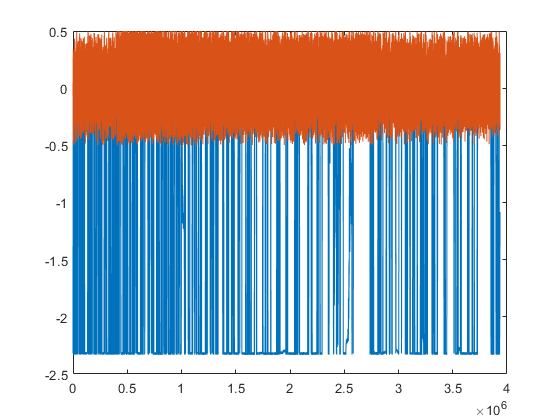

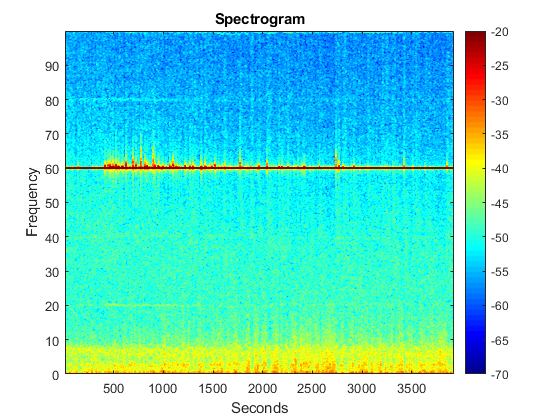

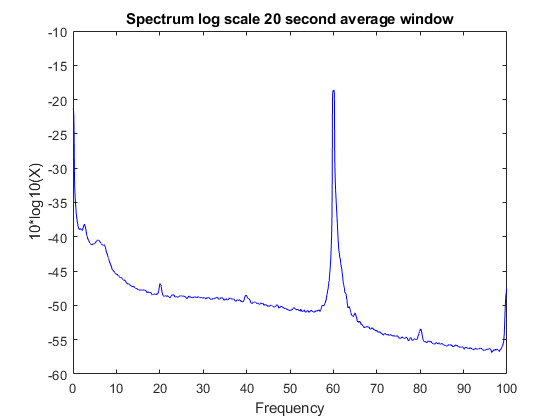

result = 1×3 cell array
    {3277×1 single}    {1×3277 double}    {3277×1 single}


ans = 'Processing Knockout 7.000000'


ans =

  1×0 empty char array



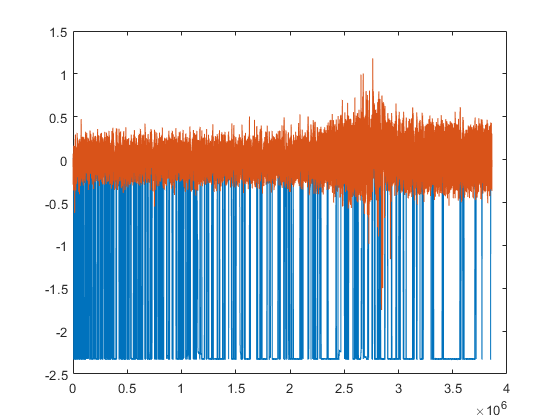

result = 3847189×2 single matrix
    0.0077   -0.0907
    0.0110   -0.0976
    0.0070   -0.0581
    0.0087   -0.0364
    0.0090   -0.0282
    0.0087   -0.0759
    0.0070   -0.0815
    0.0100   -0.0716
    0.0093   -0.0913
    0.0077   -0.1262


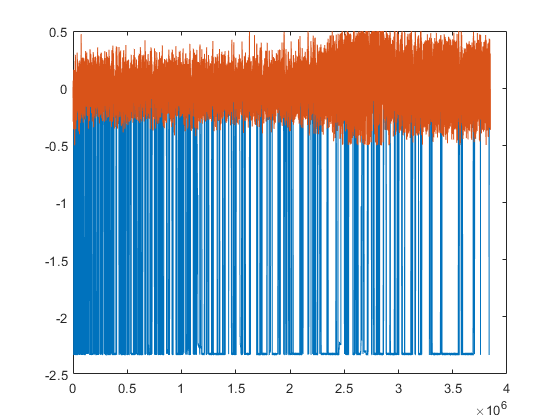

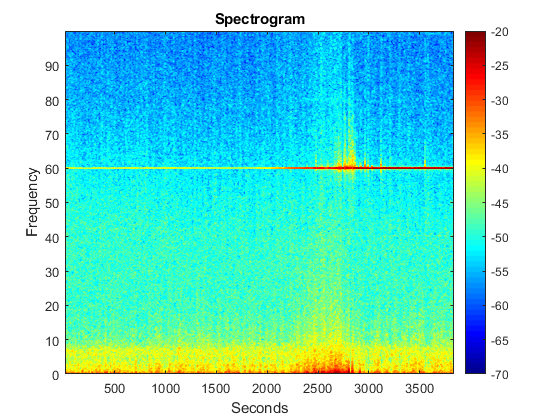

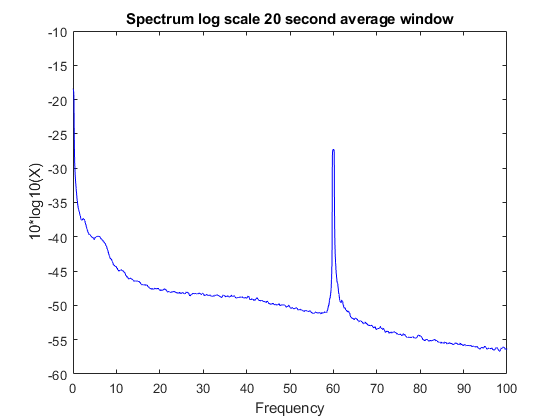

result = 1×3 cell array
    {3277×1 single}    {1×3277 double}    {3277×1 single}


x = 1872965×2 single matrix
    0.0040   -0.0496
    0.0034   -0.0759
    0.0024   -0.0456
    0.0054   -0.0561
    0.0034   -0.0413
    0.0037    0.0103
    0.0044   -0.0802
    0.0050   -0.0506
    0.0031   -0.0677
    0.0027   -0.0693


x = 5483217×2 single matrix
    0.0040   -0.0496
    0.0034   -0.0759
    0.0024   -0.0456
    0.0054   -0.0561
    0.0034   -0.0413
    0.0037    0.0103
    0.0044   -0.0802
    0.0050   -0.0506
    0.0031   -0.0677
    0.0027   -0.0693


x = 9000726×2 single matrix
    0.0040   -0.0496
    0.0034   -0.0759
    0.0024   -0.0456
    0.0054   -0.0561
    0.0034   -0.0413
    0.0037    0.0103
    0.0044   -0.0802
    0.0050   -0.0506
    0.0031   -0.0677
    0.0027   -0.0693


x = 12770663×2 single matrix
    0.0040   -0.0496
    0.0034   -0.0759
    0.0024   -0.0456
    0.0054   -0.0561
    0.0034   -0.0413
    0.0037    0.0103
    0.0044   -0.0802
    0.0050   -0.0506
    0.0031   -0.0677
    0.0027   -0.0693


x = 16462130×2 single matrix
    0.0040   -0.0496
    0.0034   -0.0759
    0.0024   -0.0456
    0.0054   -0.0561
    0.0034   -0.0413
    0.0037    0.0103
    0.0044   -0.0802
    0.0050   -0.0506
    0.0031   -0.0677
    0.0027   -0.0693


x = 20397666×2 single matrix
    0.0040   -0.0496
    0.0034   -0.0759
    0.0024   -0.0456
    0.0054   -0.0561
    0.0034   -0.0413
    0.0037    0.0103
    0.0044   -0.0802
    0.0050   -0.0506
    0.0031   -0.0677
    0.0027   -0.0693


x = 24244855×2 single matrix
    0.0040   -0.0496
    0.0034   -0.0759
    0.0024   -0.0456
    0.0054   -0.0561
    0.0034   -0.0413
    0.0037    0.0103
    0.0044   -0.0802
    0.0050   -0.0506
    0.0031   -0.0677
    0.0027   -0.0693


result = 24244855×2 single matrix
    0.0040   -0.0496
    0.0034   -0.0759
    0.0024   -0.0456
    0.0054   -0.0561
    0.0034   -0.0413
    0.0037    0.0103
    0.0044   -0.0802
    0.0050   -0.0506
    0.0031   -0.0677
    0.0027   -0.0693


Plotting All Together


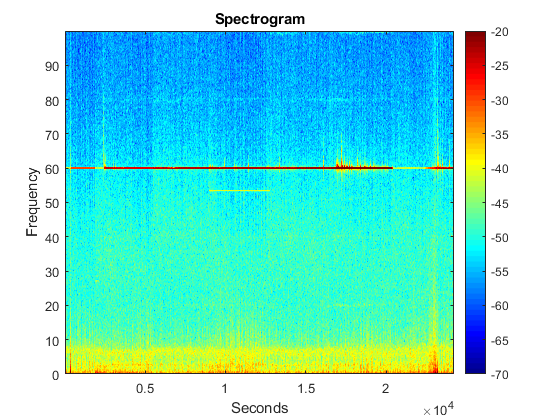

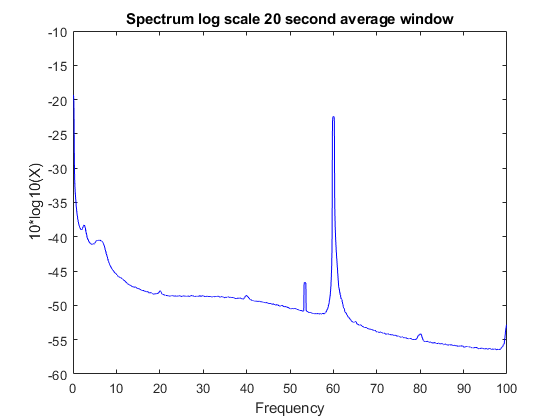

result = 1×3 cell array
    {3277×1 single}    {1×3277 double}    {3277×1 single}


x = 1×1 cell array
    {1×3 cell}


x = 1×2 cell array
    {1×3 cell}    {1×3 cell}


x = 1×3 cell array
    {1×3 cell}    {1×3 cell}    {1×3 cell}


x = 1×4 cell array
    {1×3 cell}    {1×3 cell}    {1×3 cell}    {1×3 cell}


x = 1×5 cell array
    {1×3 cell}    {1×3 cell}    {1×3 cell}    {1×3 cell}    {1×3 cell}


x = 1×6 cell array
    {1×3 cell}    {1×3 cell}    {1×3 cell}    {1×3 cell}    {1×3 cell}    {1×3 cell}


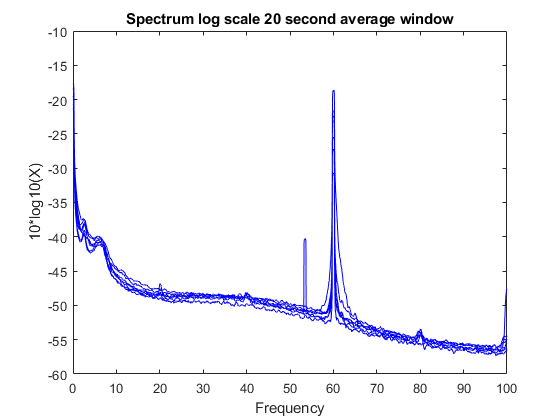

x = 1×7 cell array
    {1×3 cell}    {1×3 cell}    {1×3 cell}    {1×3 cell}    {1×3 cell}    {1×3 cell}    {1×3 cell}


result = 1×7 cell array
    {1×3 cell}    {1×3 cell}    {1×3 cell}    {1×3 cell}    {1×3 cell}    {1×3 cell}    {1×3 cell}



LFP_analysis_i(knockouts ,params, Gparams, 'Knockout') 

## Running Data

# Functions

## LFP Total Analysis Individual 

function result = LFP_analysis_i(cell_array,params, Gparams, label) 
for ii = 1:length(cell_array)
    x = cell_array{ii};
    
    sprintf ('Processing %s %f', label, ii)
    
    % Plot Raw Data
    sprintf('%S Number %f', label, ii)
    figure; plot (x);
    
    % Remove Artifacts
    x = artifact_filter(x, Gparams.artifact_filter_limit);
    
    % Plot Filtered
    figure; plot(x);
    
    plot_spectrogram(x, Gparams.movingwin, params);
    
    plot_spectrum_seg(x, Gparams.window, params);
    
    cell_array{ii} = x;    
end
cat = vertcat_cell_array(cell_array);

disp('Plotting All Together')

plot_spectrogram(cat, Gparams.movingwin, params);

plot_spectrum_seg(cat, Gparams.window,params);

plot_spectrum_seg_t_cell(cell_array, Gparams.window, params);

end

## _____________________________________________________________________________

## Calculate and Plot Spectrum Segs Together Cell Array

function result = plot_spectrum_seg_t_cell(cell_array, window, params)

% window is length in seconds to average over
segave = 1 ;
figure;

for ii = 1:length (cell_array)
    [s, f, serr] = mtspectrumsegc(cell_array{ii}(:,2),window,params,segave);
    
    plot_vector(s, f, 'l', serr); title('Spectrum log scale 20 second average window'); ylim([-60 -10]); xlabel('Frequency');
    hold on 
    
    x{ii} = {s, f, serr} 
end
result = x
end 

## Vertically Concatenate Cell Array

function result = vertcat_cell_array(cell_array)
x = cell_array{1}
for ii = 2: length(cell_array)
    x = vertcat(x,cell_array{ii}) 
end
result = x
end

## Calulate and Plot Spectrum over Average Window

function result = plot_spectrum_seg(arrayx, window, params)

% window is length in seconds to average over
segave = 1 ;
[S,f, Serr]=mtspectrumsegc(arrayx(:,2),window,params,segave);
figure; plot_vector(S,f, 'l', Serr); title('Spectrum log scale 20 second average window'); ylim([-60 -10]); xlabel('Frequency');
result = {S,f, Serr}
end

## Calculate and Plot Spectrogram

function result = plot_spectrogram (arrayx, movingwin, params)

[S2, t2, f2] = mtspecgramc(arrayx(:,2), movingwin,params);
figure; plot_matrix(S2,t2,f2); colorbar; colormap jet; caxis ([-70 -20]); xlabel('Seconds'); ylabel('Frequency');

end

## Calculate and Plot Spectrum Segs Together

function result = plot_spectrum_seg_t (arrayx, arrayz, window, params)

% window is length in seconds to average over
segave = 1 ;

% Calculate 
[S1,f1, Serr1]=mtspectrumsegc(arrayx(:,2),window,params,segave);

[S2,f2, Serr2]=mtspectrumsegc(arrayz(:,2),window,params,segave);


% Plot
figure; plot_vector(S1,f1, 'l', Serr1); title('Spectrum log scale 20 second average window'); ylim([-60 -10]); xlabel('Frequency');
hold on 
plot_vector(S2,f2, 'l', Serr2)

result = {{S1,f1, Serr1}, {S2 f2 Serr2}}
end

## Filter out Artifacts (Array)

function result = artifact_filter(array, limit)

array(abs(array(:,2)) >= limit, :) = [];

result = array
end

## Standardize Length of Arrays

function result = standardize_length(cell_array, len)
% This function takes a cell array (cell_array) containing a set of arrays
% and makes them all the same length (len) from 1 to len
for ii = 1:length(cell_array)
    cell_array{ii} = cell_array{ii}(1:len,:)
end
result = cell_array
end


## Remove Frequency Band Noise from Cell Array of Datasets

function result = filter_noise(xarray, noiseHz, Fs, alpha)
% This function removes noise from signal with variable alpha and Hz

% Set parameters for filter

omega = 2*pi*noiseHz/Fs; 
num = [1 -2*cos(omega) 1];
den = [1 -2*alpha*cos(omega) alpha*alpha];

xarray (:,2) = filter(num,den,xarray(:,2))

result = xarray
end

## Remove 60Hz Noise from Cell Array of Datasets

function result = remove60(cell_array, Fs)
% This function removes 60 Hz noise from signal

% Set parameters for filter

%%%%global params.Fs

alpha = 0.998; 
omega = 2*pi*60/Fs; 
num = [1 -2*cos(omega) 1];
den = [1 -2*alpha*cos(omega) alpha*alpha];

for ii = 1:length(cell_array)
    cell_array{ii}(:,2) = (filter(num,den,cell_array{ii}(:,2)))
end
result = cell_array
end

## Remove 60Hz Noise from Array

function result = remove60_nocell(xarray, Fs, alpha)
% This function removes 60 Hz noise from signal

% Set parameters for filter

% alpha = 0.9975; 
omega = 2*pi*60/Fs; 
num = [1 -2*cos(omega) 1];
den = [1 -2*alpha*cos(omega) alpha*alpha];

xarray (:,2) = filter(num,den,xarray(:,2))

result = xarray
end  


## ____________________________________________________________________________

## Percent Running Time

function result = percent_running(running_data)
result = sum(running_data(:) == 1)/length(running_data)
end

## Total Time Running (Seconds)

function result = time_running(running_data)
result = sum(running_data(:) == 1)
fprinf ('Total Time Running is %s \n', result)
end

## Process Running Data into Boolean per Second

function result = process_running_data(running_data)

opto = round(running_data(:,1))
times = 1:length(opto)

win = 1000; %window in ms to look at opto
winstart = [1:win:length(times)-win]; %index corresponding to the start of each window

locomotion = []; %vector of 0 (not moving) and 1 (moving) for each window (1 sec)
for i = 1:length(winstart)
   m = winstart(i);
   optowin = opto(m:m+(win-1));
   optowinDif = diff(optowin); %will be all 0 if every value in optowin is the same
   if isempty(find(optowinDif,1)) %if optowinDif are all 0's
       locomotion(i) = 0; %0 means not moving
   else
       locomotion(i) = 1; %1 = moving
   end
end
result = locomotion
end
